b0=0.00105;
b1=[1,-4,6,-4,15,1];
a1=[1,3.27,4.342,2.743,0.695];
Fs=1000;
b=b0*b1;
a=a1;

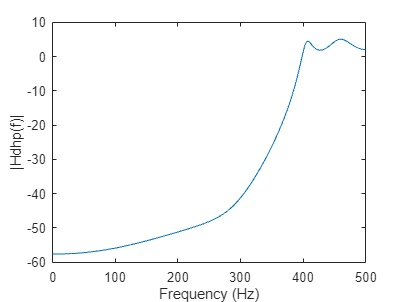

[h,w] = freqz(b,a,'whole',2001);
plot(w./pi./2.*Fs,20*log10(abs(h)))
ax = gca;
%ax.YLim = [-100 20];
ax.XLim = [0 Fs./2];
%ax.XTick = 0:.5:2;
xlabel('Frequency (Hz)')
ylabel('|Hdhp(f)|')

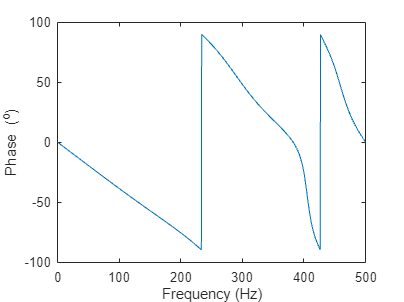

plot(w./pi./2.*Fs,angle(h)./2./pi.*180)
ax = gca;
%ax.YLim = [-100 20];
ax.XLim = [0 Fs./2];
%ax.XTick = 0:.5:2;
xlabel('Frequency (Hz)')
ylabel('Phase (^o)')

b=[1,-11.11,-180.12,-595.81,675.93-568.80,-156.77,-8.83,0.76];
a=[0.61,-6.95,-118.63,-412.34,478.96,-412.34,-118.63,-6.95,0.61];
Fs=1000;